## DKE Introduction to Bioinformatics 2022

# Assignment 4: Phylogenetic trees

Chiara Paglioni (i6249782)

**Assignment**: 

Pick a different subset of data from the nextstrain site, download the metadata file and clean it up. The file is obtained from this page [https://nextstrain.org/dengue/denv1](https://nextstrain.org/dengue/denv1)  and also reduced the number of samples, so there was only one example of each group and resaved it as a csv to load into Matlab. State a research question you want to explore using your chosen dataset (and that can be answered by building a phylogenetic tree). Then build a phylogenetic tree to answer your research question and draw some conclusions from your investigation.  

**Dengue**: 

Dengue is a viral infection transmitted to humans through the bite of infected mosquitoes. The first cases of Dengue to ever be recorded are from the 17th century but the virus is still present in the 21th century. The countries that have been affected the most by Dengue are South and Central America, South and Southeast Asia and Oceania. Moreover, some minor outbreaks of Dengue have been recorded in Africa and Europe. This information was retrieved from the metadata obtained from the following page [https://nextstrain.org/dengue/denv1](https://nextstrain.org/dengue/denv1) and from the "Dengue worldwide overview" provided by the European Centre for Disease Prevention and Control at the following page: [https://www.ecdc.europa.eu/en/dengue-monthly](https://www.ecdc.europa.eu/en/dengue-monthly) 

The following map is retrieved from the previously mentioned website and represents the spread of the Dengue virus around the world: 

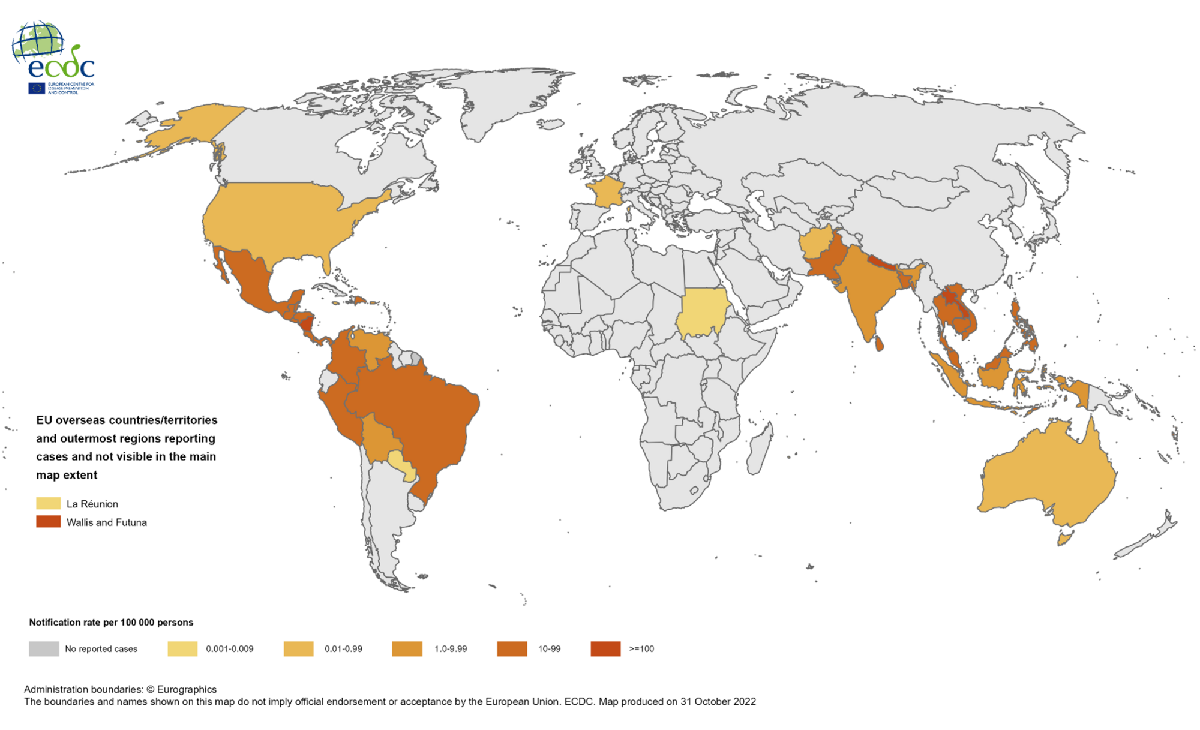

For this assignment, the focus will be on the spread of Dengue in the south of Asia and Oceania. Moreover, to further reduce the number of sequences, only some samples from a ceratin span of time are considered. 

**Research questions: **

- In which country did the proapagation of the Dengue virus originate in Asia during the 21th century (in particual from 2010 to 2020)? Are there any anomalies in the spread of the virus in Asia?

**Approach:** 

To answer the previous research question both Asia and its neighbouring countries with significant outbreaks of Dengue are considered. In particular, the following regions are selected: 

- Oceania

- South Asia 

- Southeast Asia 

Moreover, some samples from each region are choosen. The number of samples is proportional to the size of the outbreak of each country. If the virus has affected more than one country in a region, one sample from each country is selected.  Finally, the dates of the mutations of Dengue studied range from 2010 to 2020 since the virus is analysed in the 21th century.

**Read data from csv file**

data = readtable('asia_dengue.csv')

data = 13×8 table
              strain                  date       url    clade_membership         country               region                                            author                                       accession  
    ___________________________    __________    ___    ________________    _________________    __________________    __________________________________________________________________________    ____________

    {'NC_2012_02_17/048241'   }    12/07/0016    NaN     {'DENV1/I'  }      {'New Caledonia'}    {'Oceania'       }    {'Inizan et al A (https://www.ncbi.nlm.nih.gov/pubmed/33686914)'         }    {'MW315180'}
    {'NC_2012_02_17/048306'   }    10/03/0017    NaN     {'DENV1/I'  }      {'N

- Retrieve accession codes and their corresponding sequences from the csv data

n = length(data.accession);

% Retrieve accession codes from csv data
codes = char.empty(0, n);

for i = 1 : n
    codes{i} = char(data.accession(i));
end 
codes

codes = 1×13 cell array
    {'MW315180'}    {'MW315182'}    {'MK858118'}    {'MT006166'}    {'ON799266'}    {'OL587817'}    {'KY849744'}    {'KX452062'}    {'MW946129'}    {'MF033230'}    {'MW265666'}    {'MN912171'}    {'MG679801'}


% Retrieve sequences from csv data
sequences = string.empty(0, n);

for j = 1 : n
    sequences{j} = getgenbank(char(codes(j)), 'SequenceOnly', true);
end  
sequences

sequences = 1×13 string array
    "TTGTTAGTCTWCSTGGACCGACAAGAACAGTTTCGAATCGGAAGCTTGCTTAACGTAGTTCTAACAGTTTTTTATTAGAGAGCAGATCTCTGATGAACAACCAACGGAAAAAGACGGCTCGACCGTCTTTCAATATGCTGAAACGCGCGAGAAACCGCGTGTCAACTGTTTCACAGTTGGCGAAGAGATTCTCAAAAGGATTGCTTTCAGGCCAAGGACCCATGAAATTGGTGATGGCTTTCATAGCATTCCTAAGATTTCTAGCCATACCCCCAACAGCAGGAATTTTGGCTAGATGGGGCTCATTCAAGAAGAGTGGAGCGATCAAAGTGCTACGGGGTTTCAAGAAAGAAATCTCAAACATGTTGAATATAATGAATAGAAGGAAAAGATCTGTGACCATGCTCCTTATGCTGATGCCTACAGCCTTGGCGTTCCATTTGACTACACGAGGGGGAGAGCCGCACATGATAGTCAGCAAGCAGGAAAGAGGAAAGTCACTCTTGTTTAAGACCTCAGCAGGTGTCAACATGTGCACCCTTATAGCGATGGATTTGGGAGAGTTATGTGAGGACACAATGACTTACAAATGCCCTCGAATCACCGAAACTGAACCAGATGACGTTGATTGTTGGTGTAATGCCACAGACACATGGGTGACCTATGGAACATGTTCCCAAACTGGCGAGCACCGACGAGACAAACGTTCCGTCGCACTGGCCCCACACGTGGGACTTGGTTTGGAAACAAGAACCGAAACG…"    "GTTGTTAGTCTACGTGGACCGACAAGAACAGTTTCGAATCGGAAGCTTGCTTAACGTAGTTCTAACAGTTTTTTATTAGAGAGCAGATCTCTGATGAACAACCAACGGAAAAAGACGGCTCGACCGTCTTTCAATATGCTGAAACGCGCGAGAAACCGCGTGTCAACTGTTTCACAGTTGGCGAAGAGATTCTCAAA

        2. Calculate the distances between the sequences.  Use the function **seqpdist** and set **SquareForm **to be true to tell it to output a square matrix with the distances. 

distances = seqpdist(sequences, 'SquareForm', true)

distances =          0    0.0024    0.0934    0.1457    0.0912    0.3408    0.0316    0.0431    0.0820    0.0324    0.0179    0.0679    0.0340
    0.0024         0    0.0948    0.1476    0.0897    0.3421    0.0337    0.0452    0.0841    0.0312    0.0197    0.0700    0.0330
    0.0934    0.0948         0    0.0574    0.0259    0.2646    0.0956    0.1059    0.1422    0.0983    0.0980    0.1409    0.0967
    0.1457    0.1476    0.0574         0    0.0783    0.2273    0.1424    0.1383    0.0965    0.1507    0.1434    0.0955    0.1494
    0.0912    0.0897    0.0259    0.0783         0    0.2821    0.0958    0.1080    0.1454    0.0923    0.0971    0.1458    0.0918
    0.3408    0.3421    0.2646    0.2273    0.2821         0    0.3467    0.3450    0.3127    0.3465    0.3390    0.3142    0.3463
    0.0316    0.0337    0.0956    0.1424    0.0958    0.3467         0    0.0256    0.0642    0.0235    0.0338    0.0787    0.0328
    0.0431    0.0452    0.1059    0.1383    0.1080    0.3450    0.0256 

        3. The function **seqlinkage** will build the tree and save it in a variable, and then applying the **plot** function to this variable will plot the tree.  

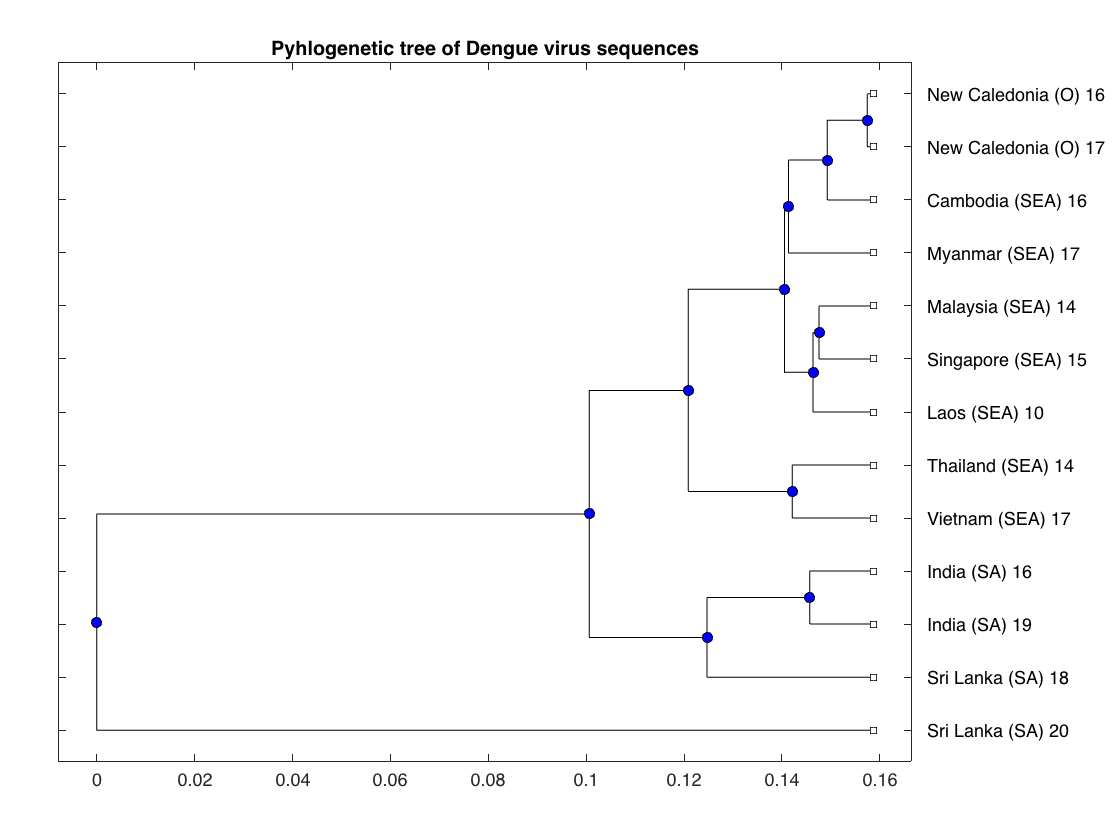

% The followig labels are set as follows: 
% - O = Oceania 
% - SA = South Asia 
% - SEA = Southeast Asia 
% Moreover the numbers written after the country's name are its
% corresponding date
labels = {'New Caledonia (O) 16', 'New Caledonia (O) 17', 'India (SA) 16', 'Sri Lanka (SA) 18', 'India (SA) 19', 'Sri Lanka (SA) 20', 'Laos (SEA) 10',  'Malaysia (SEA) 14',  'Thailand (SEA) 14',  'Singapore (SEA) 15',  'Cambodia (SEA) 16',  'Vietnam (SEA) 17',  'Myanmar (SEA) 17'};
PhyloTree = seqlinkage(distances, 'average', labels);
plot(PhyloTree);
title("Pyhlogenetic tree of Dengue virus sequences");

        4. The function **seqneighjoin **will build the tree using neighbour joining. 

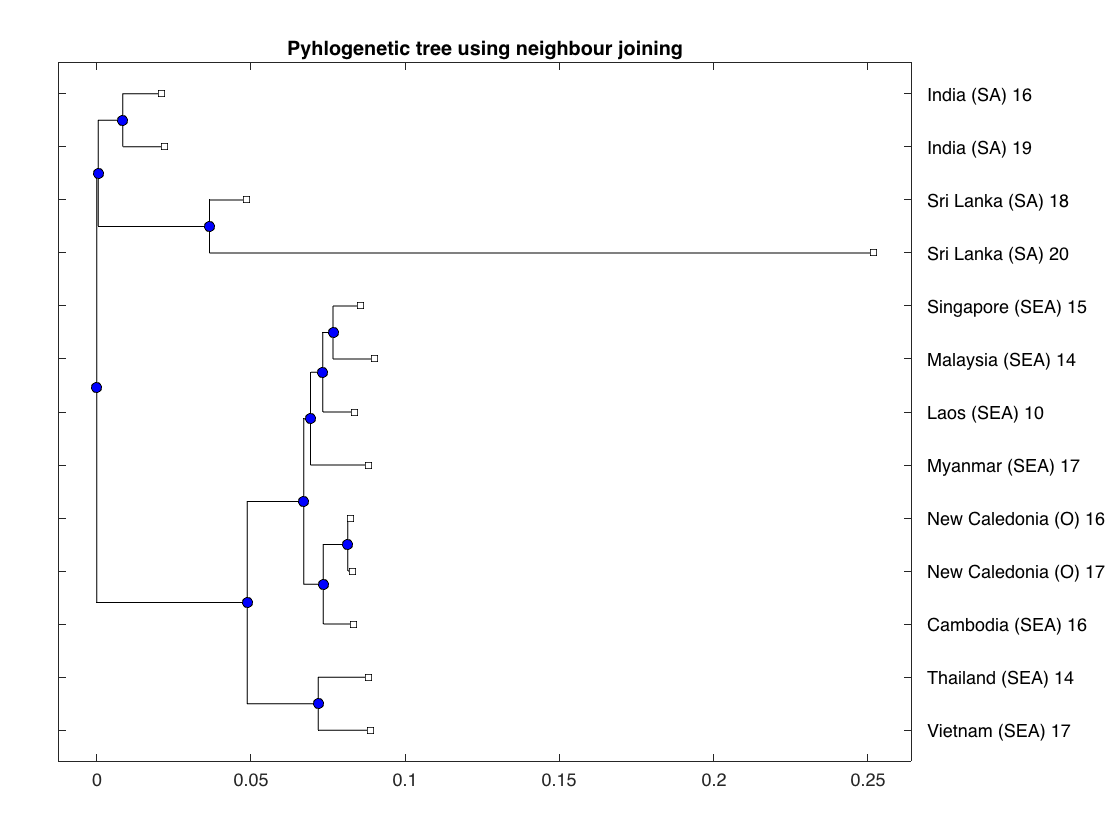

PhyloTree_neighbour = seqneighjoin(distances, 'equivar', labels);
plot(PhyloTree_neighbour)
title("Pyhlogenetic tree using neighbour joining");

        5. The distances are visualized in a plot with scaled colors using the function **imagesc**.

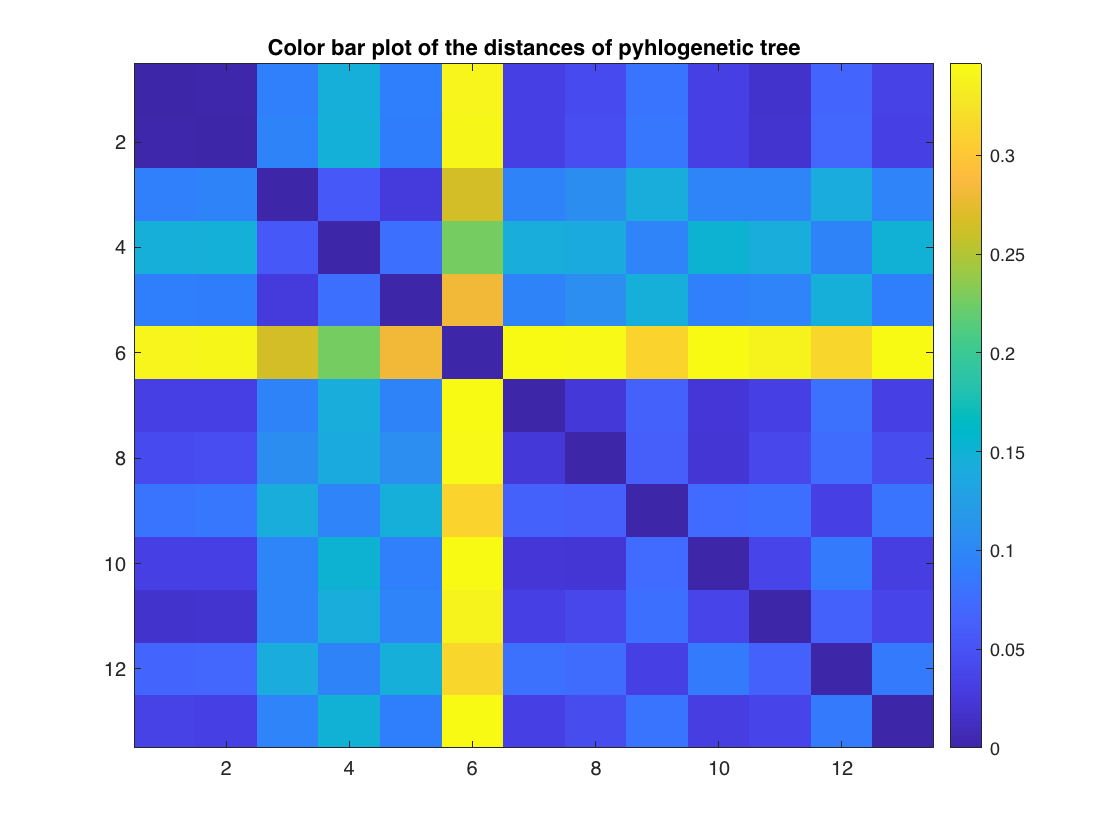

% Plot distances 
figure; 
imagesc(distances); 
colorbar;
title("Color bar plot of the distances of pyhlogenetic tree");

**Conclusions: **

By analysing the pyhlogenetic tree generated using neighbour joining and the plot of the distances, it is possible to answer the research question. As expected, the leafs of the tree that belong to the same country are grouped together since the mutation likely evolved throughout the year in the same country. Moreover, the leafs 'India (SA) 16' and 'India (SA) 19' appear to be the closest ones to the root. This means that the oldest version of the virus originated in India. At the same time, the Indian mutation did not influence other regions direclty since other countries do not appear to be connected to them. Oceania and Southeast Asia, on the other hand, are more strictly related. This can be observed again in the phylogenic tree since the leafs that belong to New Caledodia (Oceania) are connected with a leaf from Cambodia (Southeast Asia). Moreover, by looking at the same three leafs we can observe that the virus first originated in Oceania and then speread to Southeast Asia as the first ones are more close to the root. This fact can also be supported by the proximity of the two countries in the globe. 

Another interesting feature that can be observed by the pyhlogenetic tree is the big length of the branch ending with the 'Sri Lanka (20)' leaf. This means that this particual mutation of the Dengue virus has not varied for a very long period of time until 2020. The remaining sequences, on the other hand, seem to evolve very rapidly as it can be seen in the region of the plot between 0.05 to 0.1. This feature can also be observed by the color bar plot of the distances where the yellow cross in the middle of the plot represents the distance of the 'Sri Lanka (20)'  from all the other versions of the virus. As expected these distances are very big. The remaining sequences, on the contrary, are more related to one another since their distance is lower and they are equally distributed in the color bar plot. Finally, from pyhlogenetic tree it can be observed that Singapore is the sequence that has been subject to the most mutations since its leaf has many ancestors in the tree. 